handle = load("initial_data\initial_handle.mat");
seat = load("initial_data\initial_seat.mat");

range = timerange('29-Nov-2022 16:50:17.005','29-Nov-2022 16:50:56.000','closed');
handle.Acceleration = handle.Acceleration(range, :);
handle.Orientation = handle.Orientation(range, :);
seat.Acceleration = seat.Acceleration(range, :);
seat.Orientation = seat.Orientation(range, :);

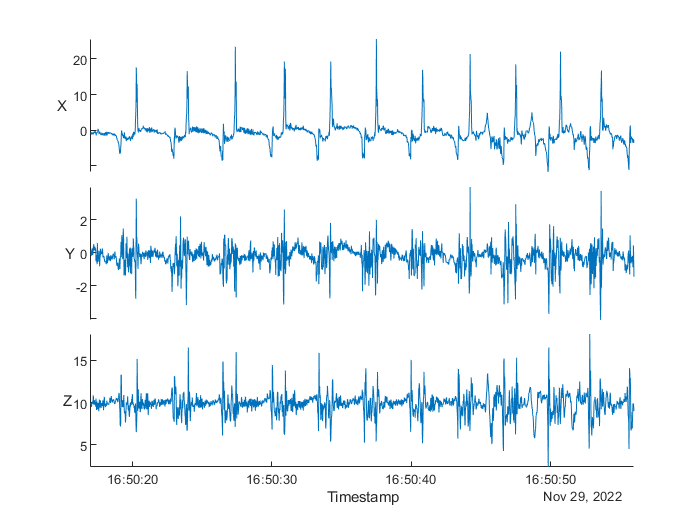

handle.Velocity = timetable(handle.Acceleration.Timestamp, cumtrapz(handle.Acceleration.X), cumtrapz(handle.Acceleration.Y), cumtrapz(handle.Acceleration.Z), 'VariableNames',{'X','Y','Z'});

handle.Position = timetable(handle.Velocity.Time, cumtrapz(handle.Velocity.X), cumtrapz(handle.Velocity.Y), cumtrapz(handle.Velocity.Z), 'VariableNames',{'X','Y','Z'});

seat.Velocity = timetable(seat.Acceleration.Timestamp, cumtrapz(seat.Acceleration.X), cumtrapz(seat.Acceleration.Y), cumtrapz(seat.Acceleration.Z), 'VariableNames',{'X','Y','Z'});

seat.Position = timetable(seat.Velocity.Time, cumtrapz(seat.Velocity.X), cumtrapz(seat.Velocity.Y), cumtrapz(seat.Velocity.Z), 'VariableNames',{'X','Y','Z'});


stackedplot(handle.Acceleration)

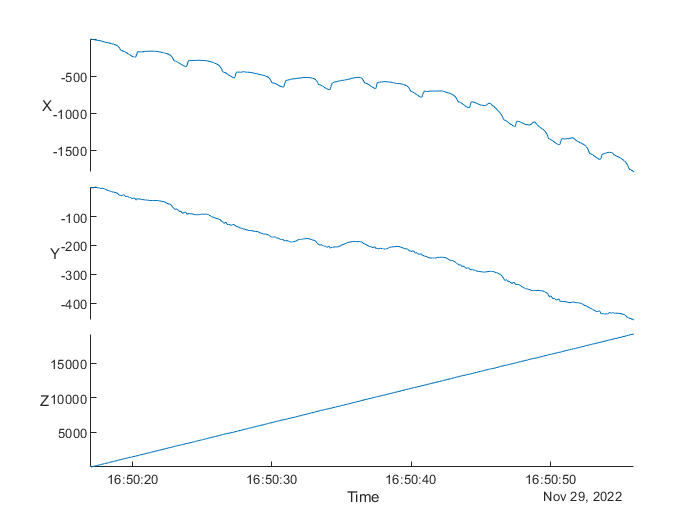

stackedplot(handle.Velocity)

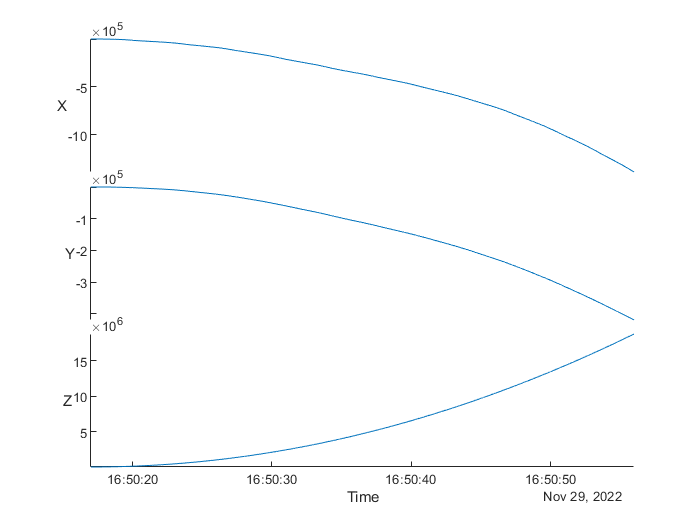

stackedplot(handle.Position)

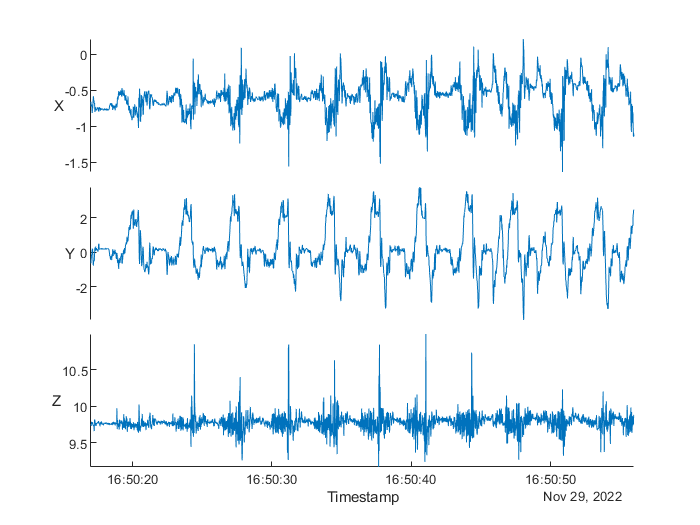


stackedplot(seat.Acceleration)

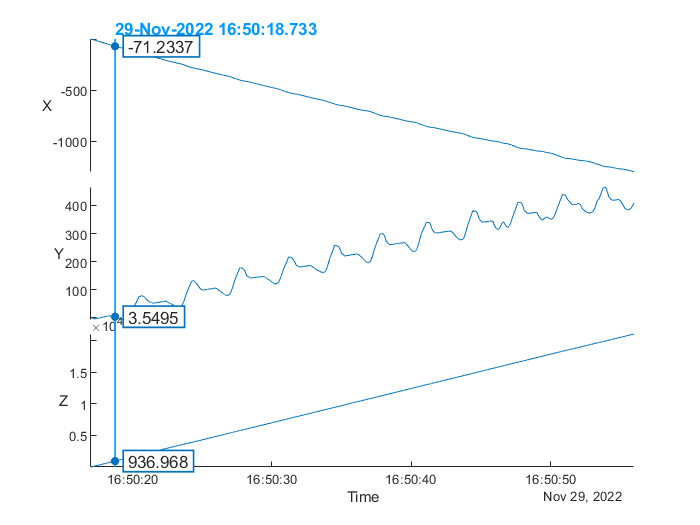

stackedplot(seat.Velocity)

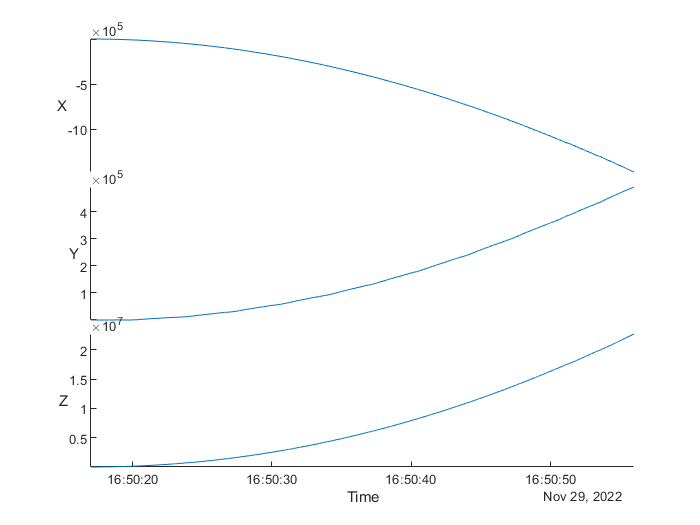

stackedplot(seat.Position)